Again, this section is quite unorganized. Make sure to properly look at the variables. Because there are so many different files, the results are everywhere. Make sure to check that the concentrations and the class labels are not present when testing the model(otherwise results are invalidated). So change the indexing accordingly

This is splitting code into training and testing

% %This is so that the chem comp can be selcted as a predictor in
% classifatioon learner
%%uncomment 
cellArrayChemComp = smoothedData.Chem_Comp;    

% Convert numbers to strings
cellArrayChemComp(cellfun(@isnumeric, cellArrayChemComp)) = cellfun(@num2str, cellArrayChemComp(cellfun(@isnumeric, cellArrayChemComp)), 'UniformOutput', false);

% Convert to categorical array
smoothedData.Chem_Comp = cell2mat(cellArrayChemComp);
class(smoothedData.Chem_Comp)
smoothedData.time=double(smoothedData.time)

% %This part is specifically splitting the data 
% %DATA SPLITTING - Train and Test Data
cv=cvpartition(size(smoothedData,1),'HoldOut',0.15);
idx=cv.test;
% 
master_Dataset_Test=smoothedData(idx,:);
masterDataset_validate=smoothedData(~idx,:); %Training Data

masterDatacopy=smoothedData;
%masterDatacopy.Chem_Comp=[]
%Convert the table into an array:
masterDataset=table2array(smoothedData)
% 
Chem_Comparray=masterDataset_validate.Chem_Comp
%not focusing on time series so it can be removed
masterDatacopy.time=[]
masterDataset_validate.time=[]
master_Dataset_Test.time=[]

**Model accuracy: 99.8%**

**Steps before testing model**

- load all of the data and perform baseline compensation

- apply moving average filter

- Normalize


load FinalClassifierModel.mat
load treeregresssmoothed.mat
propnames=masterDataset_validate(:,(2:end));
[yfit2, scores2] = FinalClassifierModel.predictFcn(master_Dataset_Test(:,2:end));
% response_array2 = master_Dataset_Test.Chem_Comp
% response_array2 = labeledmasterData_test.Chem_Comp
response_array2 = master_Dataset_Test.Chem_Comp;
ycompare=[yfit2  response_array2]

ycompare = 107868×2 char array
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '11'
    '1

% Calculate accuracy
correct_predictions2 = sum(yfit2 == response_array2);
total_predictions2 = numel(response_array2);
accuracy = correct_predictions2 / total_predictions2 * 100;

disp(['Model Accuracy: ', num2str(accuracy), '%']);

Model Accuracy: 99.822%


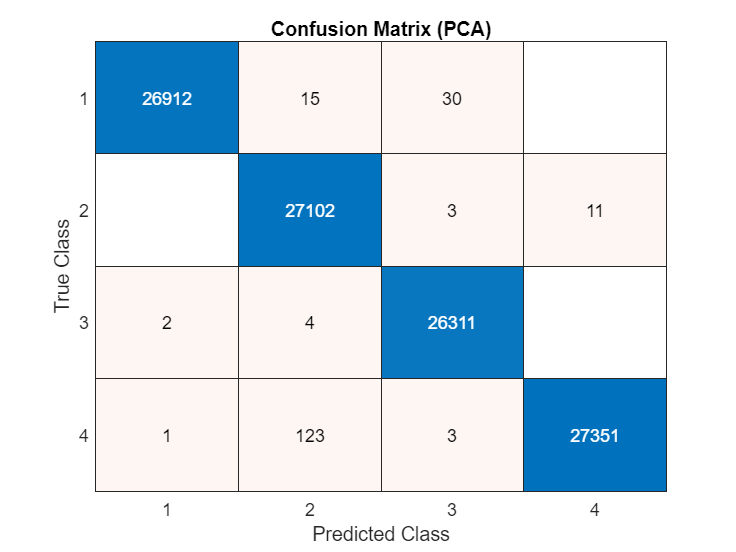


% Visualize the confusion matrix
figure;
confusionchart(response_array2, yfit2);  % <-- Use response_array1 and yfit1 here
title('Confusion Matrix (PCA)');



urine_samples_idx = find(yfit2 == '1') % Find indices of samples predicted as urine

urine_samples_idx =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


X_Urine= master_Dataset_Test(urine_samples_idx, :)% Extract features for these samples

X_Urine = 26915×12 table
    Chem_Comp      mox1         mox2        mox3       moxtemp       mics      bmetemp     bmehumidity    ccsTVOC     abshumid    sgpTVOC     sgpRawEthanol
    _________    _________    ________    ________    _________    ________    ________    ___________    ________    ________    ________    _____________

        1         -0.20207    0.029008    -0.35266     -0.11263    -0.63128    -0.42957     -0.72984      -0.98638      -0.746          -1       0.58094   
        1         -0.19438    -0.15521     -0.3536    -0.067952    -0.67876    -0.43211     -0.729

% Continue with prediction
% X_Urinetable=array2table(X_Urine)
% sourceVarNames = propnames.Properties.VariableNames;
% X_Urinetable.Properties.VariableNames = sourceVarNames

Y_pred = treeregresssmooth.predictFcn(X_Urine(:,1:end));
Y_pred = round(Y_pred)

Y_pred =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Y_Actual=master_Dataset_Test(urine_samples_idx, :);
actualconc=Y_Actual.Concentration

Error using  . 
Unrecognized table variable name 'Concentration'.


correct_pred2 = sum(Y_pred == actualconc);
total_pred2 = numel(actualconc);
accuracy = correct_pred2 / total_pred2 * 100
conccompare=[Y_pred actualconc]